Vocal Spaces v2

Rewrite the beginning bc there are the same number of faces for all the people... maybe the error is there.

clear;


% flattened spectrogram image with 21 data points
load SoundTrain.mat
load SoundTest.mat

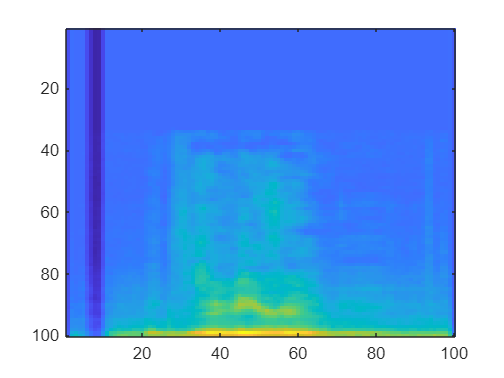

% find the mean of each class - each class is a different subject/person
flatten_size = 10000;
numData = 12; % total num of examples
numExamples = 4; % number of examples per class
numclasses = max(subject_train);
meanclass = zeros(flatten_size, numclasses);
temp = zeros(flatten_size,1);
j = 0;

for i = 1:size(grayData, 2)
    temp = temp + grayData(:,i);
    j = j+1;
    if j == numExamples
        meanclass(:, subject_train(i)) = temp/j;
        j = 0;
        temp = zeros(flatten_size,1);
    end
end

% making sure meanclass works
testimage = reshape(meanclass(:,3), 100, 100);
imagesc(testimage(:,:))

**Between Class Scatter**

sbetween = zeros(flatten_size, 1);
totalmean = mean(grayData, 2);
for i = 1:numclasses
    inside = (meanclass(i,:) - totalmean) * (meanclass(i,:) - totalmean)';
    sbetween = sbetween + numExamples*inside;
end

**WIthin Class Scatter**

swithin = zeros(flatten_size,1);
for i = 0:numclasses-1
    total = zeros(flatten_size,1);
    for j = 1:numExamples
        k = numExamples*i + j;
        inside = (grayData(:,k)-meanclass(:,i+1))*(grayData(:,k)-meanclass(:,i+1))';
        total = total + inside;
    end
    swithin = swithin + total;
end

k = 5  % number of principal components

k = 5

percent = zeros(numData,1);
    % finding principal components
    [w_pca,pca_diag]=eig(cov(grayData')); % W_pca
    w_pca = w_pca(:,1:k);
    [w_fld, diag] = eig(w_pca'*sbetween*w_pca, w_pca'*swithin*w_pca); % W_fld
    w_fld = w_fld(:,1:k);
    w_opt = (w_fld'*w_pca');
    w_opt = real(w_opt)'; % Gets rid of imaginary numbers and transposes it

    % prints fisher faces
    % for i = 1: k
    %     figure;
    %     testimage = reshape(w_opt(:,i), 64, 64);
    %     imagesc(testimage(:,:)); colormap('gray');
    % end

    % finding the projection
    projectiontrain = grayData'*w_opt;
    projectiontest = grayTest'*w_opt;


     % checking each test spectrogram against each train spectrogram to
     % determine the closest distance
     guess = zeros(size(projectiontest,1),1);
     for test = 1:size(projectiontest,1)
         least = 10000;
         for train = 1:size(projectiontrain,1)
             p = projectiontest(test,:);
             q = projectiontrain(train,:);
             dist = sum(abs(p-q));
             if dist < least
                 least = dist;
                 guess(test) = subject_train(train);
             end
         end
     end
     
     % check how many are right
     numcorrect = 0;
     for i = 1:size(guess,1)
         if guess(i) == subject_test(i)
             numcorrect = numcorrect + 1;
         end
     end
     
     percentcorrect = numcorrect/size(grayTest,2);
     

disp(numcorrect);

     1



disp(percentcorrect);

    0.3333

